clc;
close all;
clear all
% Read the image and corresponding threshold value from .csv file for training and testing 
trainingData = readtable("Train.csv");
X_Train = trainingData.Name;
testingData = readtable("Test.csv");
X_Test = testingData.Name;

% Threshold value for testing and training
Y_Train = trainingData.Value;
Y_Test = testingData.Value;
fn = X_Train{1};
size(imread(fn));

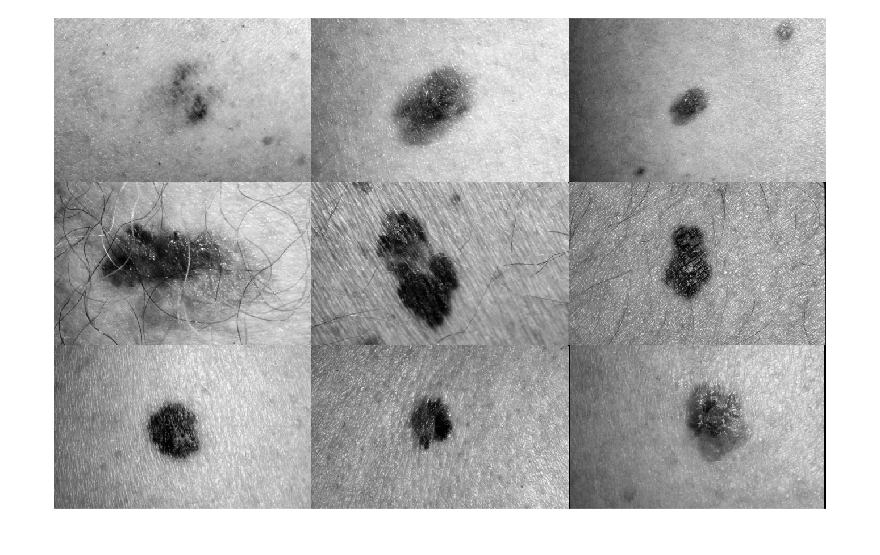

% Display 9 sample images from the database
imds = imageDatastore(X_Train(1:9));
montage(imds)

trainds = augmentedImageDatastore([224 224],trainingData);
testds = augmentedImageDatastore([224 224],testingData);

%DTP-Net Layers

layers = [
    imageInputLayer([224 224 1])
    convolution2dLayer(3,8,'Padding','same')
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,16,'Padding','same')
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,32,'Padding','same')
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,64,'Padding','same')
    convolution2dLayer(3,64,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,128,'Padding','same')
    convolution2dLayer(3,128,'Padding','same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,256,'Padding','same')
    batchNormalizationLayer
    reluLayer
    dropoutLayer(0.2)
    fullyConnectedLayer(1)
    regressionLayer];

options = trainingOptions("sgdm","MaxEpochs",150,"InitialLearnRate",0.0001,'Shuffle','every-epoch', ...
    'MiniBatchSize',64)

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-04
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 150
                   MiniBatchSize: 64
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
                       OutputFcn:



% options = trainingOptions("sgdm","MaxEpochs",500,"InitialLearnRate",0.0001, ...
%     'ValidationData',{validds,YValid},'ValidationFrequency',10, ...
%     'MiniBatchSize',8,'Plots','training-progress')


% miniBatchSize  = 128;
% validationFrequency = floor(numel(YTrain)/miniBatchSize);
% options = trainingOptions('sgdm', ...
%     'MiniBatchSize',miniBatchSize, ...
%     'MaxEpochs',30, ...
%     'InitialLearnRate',1e-3, ...
%     'LearnRateSchedule','piecewise', ...
%     'LearnRateDropFactor',0.1, ...
%     'LearnRateDropPeriod',20, ...
%     'Shuffle','every-epoch', ...
%     'ValidationData',{testds,YTrain}, ...
%     'ValidationFrequency',validationFrequency, ...
%     'Plots','training-progress', ...
%     'Verbose',false);

%Train the DTP-Net
ccnet = trainNetwork(trainds,layers,options)

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:25 |       120.00 |       7199.5 |      1.0000e-04 |
|       1 |          50 |       00:00:46 |        26.10 |        340.5 |      1.0000e-04 |
|       2 |         100 |       00:01:19 |        20.91 |        218.6 |      1.0000e-04 |
|       3 |         150 |       00:01:51 |        21.26 |        225.9 |      1.0000e-04 |
|       3 |         200 |       00:02:12 |        30.24 |        457.3 |      1.0000e-04 |
|       4 |         250 |       00:02:44 |        23.98 |        287.5 |      1.0000e-04 |
|       5 |         300 |  

ccnet =   SeriesNetwork with properties:

         Layers: [31×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'regressionoutput'}


% Prediction of Threshold value using the trained DTP-Net
Train_Predicted = predict(ccnet,trainds);
Test_Predicted = predict(ccnet,testds);

% Error estimation
Train_predictionError = Y_Train - Train_Predicted;
Test_predictionError = Y_Test - Test_Predicted;

% Evalaution for training data
Train_Pred_mae = errperf(Y_Train,Train_Predicted,'mae')

Train_Pred_mae = single
5.1116

Train_Pred_mse = errperf(Y_Train,Train_Predicted,'mse')

Train_Pred_mse = single
40.5576

Train_Pred_rmse = errperf(Y_Train,Train_Predicted,'rmse')

Train_Pred_rmse = single
6.3685

%Train_Pred_mare = errperf(Y_Train,Train_Predicted,'mare')
%Train_Pred_msre = errperf(Y_Train,Train_Predicted,'msre')
%Train_Pred_rmsre = errperf(Y_Train,Train_Predicted,'rmsre')
%Train_Pred_mape = errperf(Y_Train,Train_Predicted,'mape')
%Train_Pred_mspe = errperf(Y_Train,Train_Predicted,'mspe')
%Train_Pred_rmspe = errperf(Y_Train,Train_Predicted,'rmspe')

% Evalaution for test data
Test_Pred_mae = errperf(Y_Test,Test_Predicted,'mae')

Test_Pred_mae = single
6.2166

Test_Pred_mse = errperf(Y_Test,Test_Predicted,'mse')

Test_Pred_mse = single
48.8017

Test_Pred_rmse = errperf(Y_Test,Test_Predicted,'rmse')

Test_Pred_rmse = single
6.9858

% Test_Pred_mare = errperf(Y_Test,Test_Predicted,'mare')
% Test_Pred_msre = errperf(Y_Test,Test_Predicted,'msre')
% Test_Pred_rmsre = errperf(Y_Test,Test_Predicted,'rmsre')
% Test_Pred_mape = errperf(Y_Test,Test_Predicted,'mape')
% Testn_Pred_mspe = errperf(Y_Test,Test_Predicted,'mspe')
% Test_Pred_rmspe = errperf(Y_Test,Test_Predicted,'rmspe')

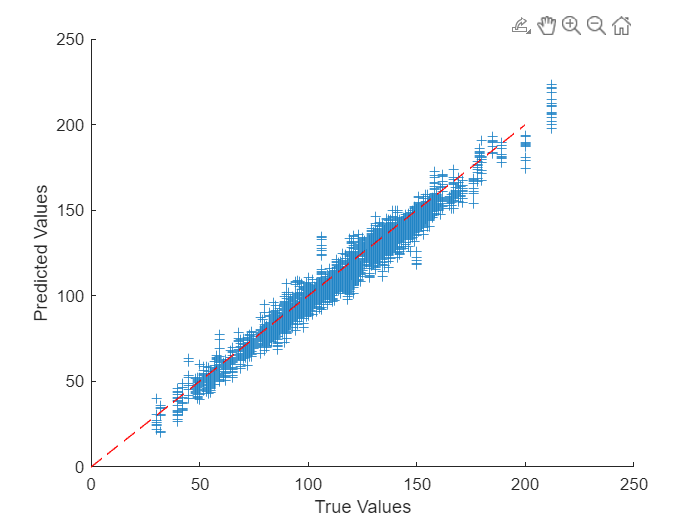

% Scatter plot for training phase
figure
scatter(Y_Train,Train_Predicted,'+')
xlabel("True Values")
ylabel("Predicted Values")

hold on
plot([0 200], [0 200],'r--')

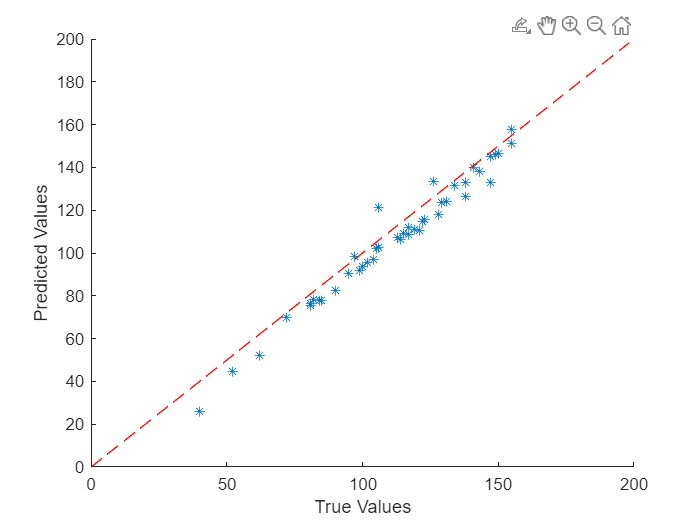

% Scatter plot for testing phase
figure
scatter(Y_Test,Test_Predicted,'*')
xlabel("True Values")
ylabel("Predicted Values")

hold on
plot([0 200], [0 200],'r--')

%ccnet.Layers